Now that we have calculated and plotted the tuning curve for one cell, it should be relatively straightforward to replicate our code from Step 4 for all cells. The key difference is that `AveON` and `AveOFF` need to be 3-dimensional matrices, with size **NumCells x NumOrientations x NumTrials.**

load('DFF.mat');
             
NumCells = size(DFF,1);

SamplesPerOri = 40;
NumOrientations = 12;
NumTrials = 6;

% initialize matrices
AveON = zeros(NumCells,NumOrientations,NumTrials);
AveOFF = zeros(NumCells,NumOrientations,NumTrials);

Write a `for` loop that extracts the time-avergaed response matrices for each cell.

for cell = 1:NumCells            
    
    dff_cell = DFF(cell,:); % extract dff trace for our cell
    dff_reshaped = reshape(dff_cell,SamplesPerOri,NumOrientations,NumTrials);
    
    ON_period = 21:40;
    OFF_period = 11:20;
        
    cell_AveON = mean(dff_reshaped(ON_period,:,:), 1);
    cell_AveOFF = mean(dff_reshaped(OFF_period,:,:), 1);        
        
    AveON(cell,:,:) = cell_AveON;
    AveOFF(cell,:,:) = cell_AveOFF;
end

Using the new 3D `AveON` and `AveOFF` matrices, plot tuning curves for 8 of your cells. Assign `ON_mean `and `ON_sem` as 2D matrices (size NumCells x NumOrientations), and assign `OFF_mean` as a one-dimensional vector (size NumCells). Don't forget to assign your baseline as `OFF_line`.

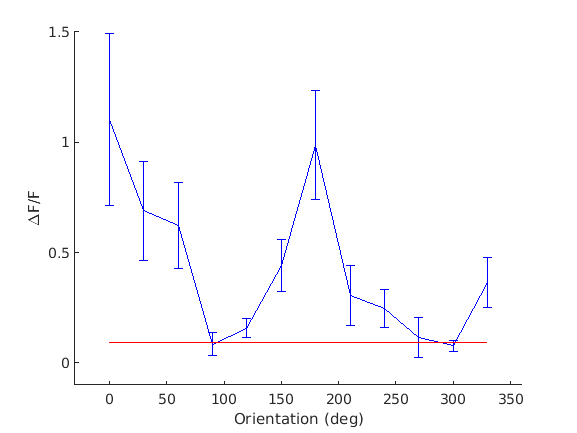

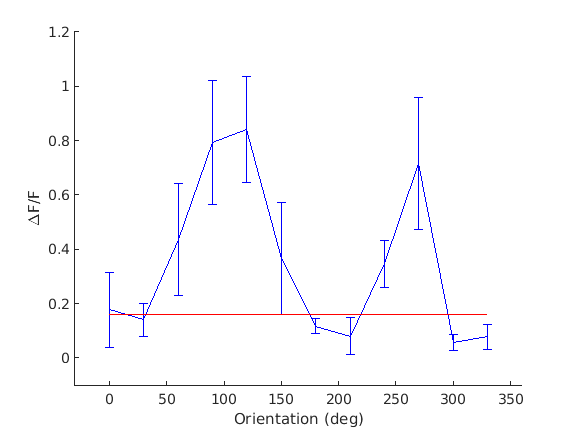

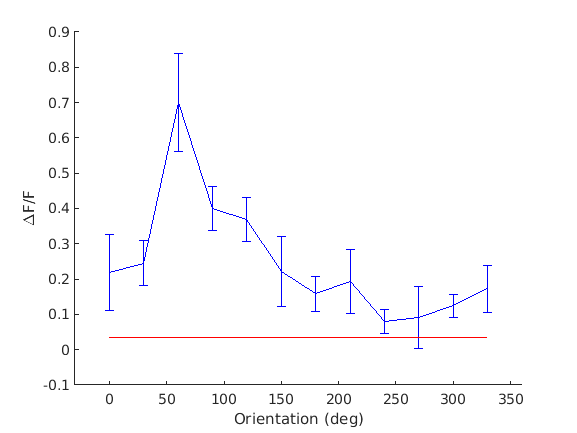

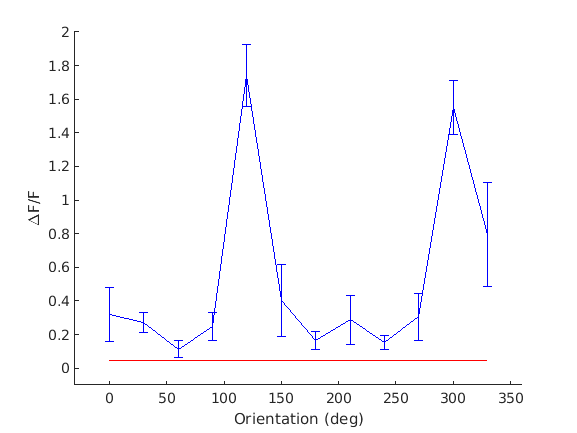

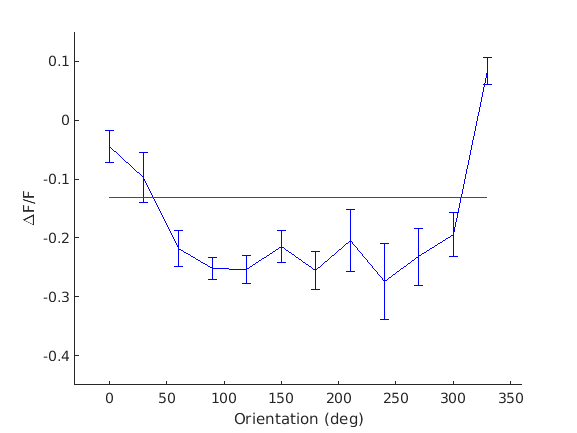

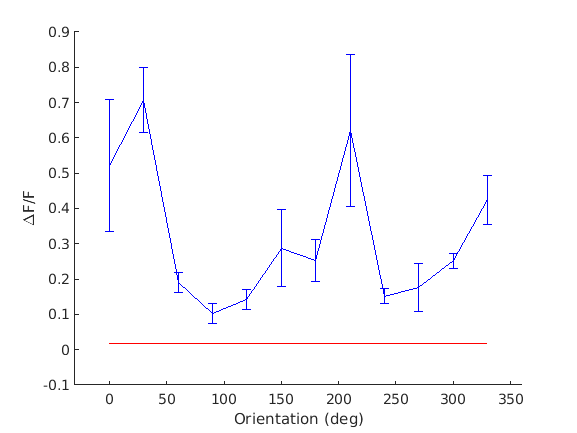

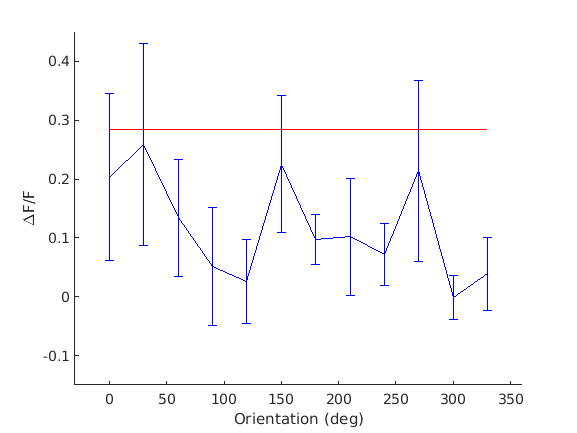

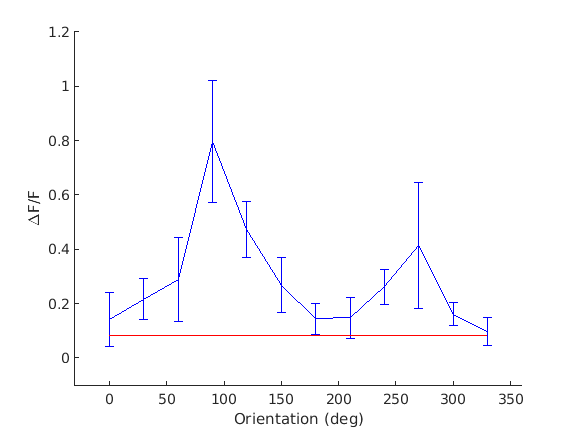

Orientations = 0:30:330;
        
ON_mean = mean(AveON,3);
ON_sem = std(AveON,[],3)/sqrt(NumTrials);
        
OFF_mean = mean(mean(AveOFF,3),2);

for cell = 1:8
    figure()
    
    OFF_line = OFF_mean(cell)*ones(size(Orientations)); % this generates a baseline you can plot 
        
	hold on
	errorbar(Orientations,ON_mean(cell,:),ON_sem(cell,:),'b') % plot ON tuning curve       
    plot(Orientations,OFF_line,'r') % plot OFF spontaneous activity
	xlim([-30 360])
	ylim([min(ylim)-0.1, max(ylim)])
        xlabel('Orientation (deg)')
        ylabel('\DeltaF/F') 
end